%% Script to get reduced brightness image using JND_pixel.m using lab colour space

img_list = ["input/fruit.jpg";"input/library.jpg";"input/ubc.jpg"];

for idx = 1:numel(img_list)

% Hyperparameters
HF_MULTIPLIER = 2;
Reduce_factor = 0.6;
Enhance_factor = 3.0;

% Original images
Orig_img = imread(img_list(idx));

% Dim the original image
Dim_img = dim_image(Orig_img, Reduce_factor);
[path,input_filename, ext] = fileparts(img_list(idx));
dimmed_file = "tmp/" + input_filename + "_dimmed" + ext;
imwrite(Dim_img, dimmed_file, 'jpg');

% Enhance the dimmed image with CSF method
enhanced_file = "tmp/" + input_filename + "_enhanced" + ext;
system("java Contrast " + dimmed_file + " " + enhanced_file + " " + Enhance_factor);
enhance_img = imread(enhanced_file);


Reading input file.
Dimensions3 1067 1600
Converted the Image to Lxy notation
Generated the Maximum Envelop
Starting first pass.
 Number of components is 1
Number of hillocks is 1
 Number of components is 497
Number of hillocks is 5
 Number of components is 6
Number of hillocks is 9
 Number of components is 1
Number of hillocks is 9
 Number of components is 0
Number of hillocks is 8
 Number of components is 1
Number of hillocks is 8
 Number of components is 0
Number of hillocks is 7
 Number of components is 0
Number of hillocks is 6
 Number of components is 0
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 N

Reading input file.
Dimensions3 529 700
Converted the Image to Lxy notation
Generated the Maximum Envelop
Starting first pass.
 Number of components is 1
Number of hillocks is 1
 Number of components is 280
Number of hillocks is 1
 Number of components is 736
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 0
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hi

Reading input file.
Dimensions3 651 970
Converted the Image to Lxy notation
Generated the Maximum Envelop
Starting first pass.
 Number of components is 1
Number of hillocks is 1
 Number of components is 146
Number of hillocks is 1
 Number of components is 496
Number of hillocks is 13
 Number of components is 5
Number of hillocks is 15
 Number of components is 2
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 0
Number of hillocks is 15
 Number of components is 1
Number of hillocks is 15
 Number of components is 1
Number of hillocks is 15
 Number of components is 0
Number of hi

Original brightness: 37.2808


Dimmed brightness: 22.0186


Enhanced brightness: 30.7178


Reduced brightness: 16.8386


Original brightness: 31.6675


Dimmed brightness: 18.5509


Enhanced brightness: 29.045


Reduced brightness: 14.8115


Original brightness: 58.4983


Dimmed brightness: 35.9788


Enhanced brightness: 52.2044


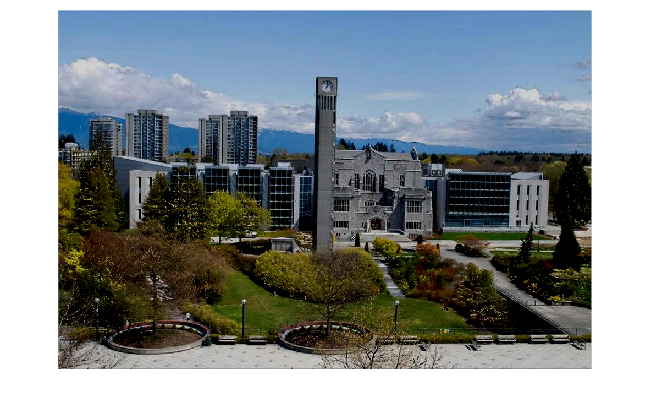

Reduced brightness: 39.3987


% Scale image down using imresize to be compatible with JND_pixel.m if
% needed
%[numRows, numCols] = size(enhance_img);
%if numRows > 383
    % Determine scaling factor needed and round to 1 decimal place
   % scaling_factor = floor(10*383/numRows)/10;
%else
    %scaling_factor = 1;
%end

I = enhance_img;

% Get high frequency multiplier matrix
y = get_HF_multiplier(I, HF_MULTIPLIER);

% Convert to lab colour space using rgb2lab
lab_im = rgb2lab(I);
lab_y_im = lab_im(:,:,1);

% Reduce JND
% Run JND_pixel 
JND_im = JND_pixel(lab_y_im, 'Yang');
mult_JND_im = times(JND_im, y);

% Reduce brightness of luminance image by JND values
new_im = lab_y_im - mult_JND_im;

% Update modified L channel
lab_im(:,:,1) = new_im;

% Convert back to rgb 
rgb_im = lab2rgb(lab_im, 'OutputType', 'uint8');

% Calculate brightness change
orig_y = calc_lab_brightness(Orig_img);
dim_y = calc_lab_brightness(Dim_img);
enhance_y = calc_lab_brightness(enhance_img);
new_y = calc_lab_brightness(rgb_im);

% Display the original image
imshow(Orig_img);
disp(['Original brightness: ' num2str(orig_y)]);

% Display the dimmed image
imshow(Dim_img);
disp(['Dimmed brightness: ' num2str(dim_y)]);

% Display the enhanced image
imshow(enhance_img);
disp(['Enhanced brightness: ' num2str(enhance_y)]);

% Display the brightness-reduced image
imshow(rgb_im);
disp(['Reduced brightness: ' num2str(new_y)]);

% Save the images to an output directory
imwrite(Orig_img, 'output/' + input_filename + '_' + num2str(dim_y) + '_input.jpg', 'jpg');
imwrite(Dim_img, 'output/' + input_filename + '_' + num2str(dim_y) + '_dimmed.jpg', 'jpg');
imwrite(enhance_img, 'output/' + input_filename + '_' + num2str(enhance_y) + '_enhanced.jpg', 'jpg');
imwrite(rgb_im, 'output/' + input_filename + '_' + num2str(new_y) + '_output.jpg', 'jpg');
end

delete('tmp/*'); % Delete intermediate output from Java code
